# 球谐函数类编写说明

## 定义				

### Associated Legendre polynomials 


$$P_{\ell}^{m}(x)=\frac{(-1)^{m}}{2^{\ell} \ell !}\left(1-x^{2}\right)^{m / 2} \frac{d^{\ell+m}}{d x^{\ell+m}}\left(x^{2}-1\right)^{\ell}, \quad \text { for }-1 \leq x \leq 1, \ell \geq 0,-\ell \leq m \leq \ell$$


%simplify(Y_l__m.Plm(0,4,'triangle',false))
%simplify(Y_l__m.Plm(4,4,'ClosedForm',true,'triangle',false))
for l =0:4
    for m = 0:l
        eval("P_"+num2str(l)+"__"+num2str(m)+" = "+"simplify(Y_l__m.Plm(l,m,'ClosedForm',true,'triangle',false))");
        %eval("P_"+num2str(l)+"__"+num2str(m)+" = "+"Y_l__m.Plm(l,m)");
        %eval("P_"+num2str(l)+"__"+num2str(m)+" = "+"Y_l__m.Plm(l,m,'ClosedForm',true)");
    end
end

$$P\_0\_\_0 = 1$$

$$P\_1\_\_0 = x$$

$$P\_1\_\_1 = -\sqrt{1-x^{2}}$$

$$P\_2\_\_0 = -\frac{1}{2}+\frac{3\,x^{2}}{2}$$

$$P\_2\_\_1 = -3\,x\,\sqrt{1-x^{2}}$$

$$P\_2\_\_2 = 3-3\,x^{2}$$

$$P\_3\_\_0 = \frac{x\,\left(-3+5\,x^{2}\right)}{2}$$

$$P\_3\_\_1 = -8\,\sqrt{1-x^{2}}\,\left(-\frac{3}{16}+\frac{15\,x^{2}}{16}\right)$$

$$P\_3\_\_2 = -15\,x\,\left(-1+x^{2}\right)$$

$$P\_3\_\_3 = -15\,{\left(1-x^{2}\right)}^{3/2}$$

$$P\_4\_\_0 = \frac{3}{8}-\frac{15\,x^{2}}{4}+\frac{35\,x^{4}}{8}$$

$$P\_4\_\_1 = -\frac{5\,x\,\sqrt{1-x^{2}}\,\left(-3+7\,x^{2}\right)}{2}$$

$$P\_4\_\_2 = -\left(-16+16\,x^{2}\right)\,\left(-\frac{15}{32}+\frac{105\,x^{2}}{32}\right)$$

$$P\_4\_\_3 = -105\,x\,{\left(1-x^{2}\right)}^{3/2}$$

$$P\_4\_\_4 = 105\,{\left(-1+x^{2}\right)}^{2}$$

### fully normalized associated Legendre functions 


$$N_{\ell}^{m}=(-1)^{m} \sqrt{\frac{\left(\ell+\frac{1}{2}\right) !(\ell-m) !}{(\ell+m) !}} P_{\ell}^{m}$$
					

### spherical harmonic 


$$Y_{\ell}^{m}(\theta, \phi)=\sqrt{\frac{(2 \ell+1)}{4 \pi} \frac{(\ell-m) !}{(\ell+m) !}} P_{\ell}^{m}(\cos \theta) e^{i m \phi}$$


or equals


$$Y_{\ell}^{m}(\theta, \phi)=(-1)^{m} \sqrt{\frac{1}{2 \pi}} N_{\ell}^{m}(\cos \theta) e^{i m \phi}$$


Y_1__0 = Y_l__m(1,0,'symbolic',true)

Y_1__0 = (3^(1/2)*cos(theta))/(2*pi^(1/2))
 

Y_1__0.expression

$$ans = \frac{\sqrt{3}\,\cos\left(\theta \right)}{2\,\sqrt{\pi }}$$

Y_l__m(1,0,'symbolic',true)+Y_l__m(2,0,'symbolic',true)

ans = (3^(1/2)*cos(theta))/(2*pi^(1/2)) + (5^(1/2)*(3*cos(theta)^2 - 1))/(4*pi^(1/2))
 

ans.formula('explicit',true)

$$ans = \frac{\sqrt{3}\,\cos\left(\theta \right)}{2\,\sqrt{\pi }}+\frac{\sqrt{5}\,\left(3\,{\cos\left(\theta \right)}^{2}-1\right)}{4\,\sqrt{\pi }}$$

Y_l__m(1,0,'symbolic',true)+Y_l__m(1,0,'symbolic',true)

ans = (3^(1/2)*cos(theta))/(2*pi^(1/2))
 

ans.formula

$$ans = 2.0\,Y_{1}^{0}$$

simplify(Y_l__m.InnerY_l__m(1,0))

$$ans = \frac{\sqrt{3}\,\cos\left(\theta \right)}{2\,\sqrt{\pi }}$$

### real spherical harmonic 


$$Y_{\ell m}= \begin{cases}\frac{i}{\sqrt{2}}\left(Y_{\ell}^{m}-(-1)^{m} Y_{\ell}^{-m}\right) & \text { if } m<0 \\ Y_{\ell}^{0} & \text { if } m=0 \\ \frac{1}{\sqrt{2}}\left(Y_{\ell}^{-m}+(-1)^{m} Y_{\ell}^{m}\right) & \text { if } m>0\end{cases}$$


The real spherical harmonics are sometimes known as *tesseral spherical harmonics*.

The real spherical harmonics $Y_{\textrm{lm}}$ with *m* > 0 are said to be of cosine type, and those with *m* < 0 of sine type. The reason for this can be seen by writing the functions in terms of the Legendre polynomials as


$$Y_{{\ell}m}(\theta, \phi) = \frac{1}{\sqrt{\pi}}N_{\ell}^m(\cos \theta) cos(m\phi), m>0
$$



$$Y_{{\ell}m}(\theta, \phi) = \frac{1}{\sqrt{2\pi}}N_{\ell}^m(\cos \theta), m=0$$



$$
Y_{{\ell}m}(\theta, \phi) = \frac{1}{\sqrt{\pi}}N_{\ell}^{-m}(\cos \theta) sin(-m\phi), m<0$$


simplify(Y_lm(1,-1).formula('explicit',true))

$$ans = \frac{\sqrt{3}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)}{2\,\sqrt{\pi }}$$


$$Y_{\ell}^{m}= \begin{cases}\frac{1}{\sqrt{2}}\left(Y_{\ell|m|}-i Y_{\ell,-|m|}\right) & \text { if } m<0 \\ Y_{\ell 0} & \text { if } m=0 \\ \frac{(-1)^{m}}{\sqrt{2}}\left(Y_{\ell|m|}+i Y_{\ell,-|m|}\right) & \text { if } m>0\end{cases}$$


py = Y_lm(1,-1);
Tesseralexpansion = py.Tesseral;
Tesseralexpansion{1}

ans =      1    -1


Tesseralexpansion{2}

$$ans = 1$$

### **Separated Cartesian form**


$$$$
r^{\ell}\left(\begin{array}{c}
Y_{\ell}^{m} \\
Y_{\ell}^{-m}
\end{array}\right)=\left[\frac{2 \ell+1}{4 \pi}\right]^{1 / 2} \bar{\Pi}_{\ell}^{m}(z)\left(\begin{array}{c}
(-1)^{m}\left(A_{m}+i B_{m}\right) \\
\left(A_{m}-i B_{m}\right)
\end{array}\right), \quad m>0
$$$$


and for m=0


$$r^{\ell} Y_{\ell}^{0} \equiv \sqrt{\frac{2 \ell+1}{4 \pi}} \bar{\Pi}_{\ell}^{0}$$


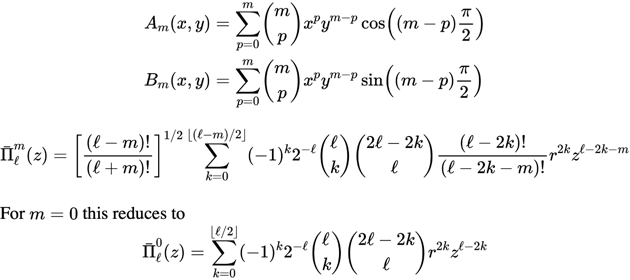

simplify(Y_l__m(1,0).formula('explicit',true,'cart',true))

$$ans = p_{z}$$

simplify(Y_l__m.InnerY_l__m(1,-1,'triangle',false))

$$ans = \frac{\sqrt{6}\,\left(r^{2}-z^{2}\right)}{4\,r\,\sqrt{\pi }\,\left(y\,\mathrm{i}+x\right)}$$

## 特点

### Special cases and values

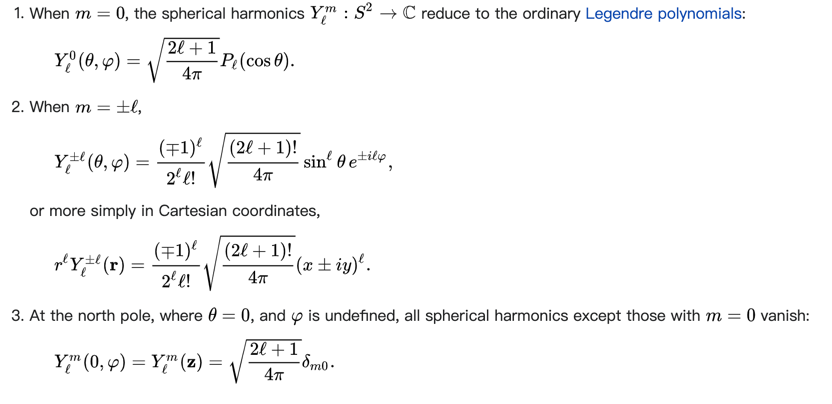

### **Contraction rule**


$$Y_{a, \alpha}(\theta, \varphi) Y_{b, \beta}(\theta, \varphi)=\sqrt{\frac{(2 a+1)(2 b+1)}{4 \pi}} \sum_{c, \gamma}(-1)^{\gamma} \sqrt{2 c+1}\left(\begin{array}{ccc}
a & b & c \\
\alpha & \beta & -\gamma
\end{array}\right)\left(\begin{array}{ccc}
a & b & c \\
0 & 0 & 0
\end{array}\right) Y_{c, \gamma}(\theta, \varphi)$$



$$Y_{\ell_{1}}^{m_{1}}(\Omega) Y_{\ell_{2}}^{m_{2}}(\Omega)=\sum_{L, M} \sqrt{\frac{\left(2 \ell_{1}+1\right)\left(2 \ell_{2}+1\right)}{4 \pi(2 L+1)}}\left\langle\ell_{1} 0 \ell_{2} 0 \mid L 0\right\rangle\left\langle\ell_{1} m_{1} \ell_{2} m_{2} \mid L M\right\rangle Y_{L}^{M}(\Omega)$$


#### Examples


$$Y_{1,0}(\theta, \phi) \cdot Y_{1,0}(\theta, \phi)=\frac{1}{2} \sqrt{\frac{3}{\pi}} \cos \theta \cdot \frac{1}{2} \sqrt{\frac{3}{\pi}} \cos \theta=\frac{3}{4 \pi} \cos ^2 \theta$$


(Y_l__m(1,0,'symbolic',true)*Y_l__m(1,0,'symbolic',true))

ans = (3*cos(theta)^2 - 1)/(4*pi) + 1/(4*pi)
 

ans.formula('vpa',false)

$$ans = \frac{\sqrt{5}\,Y_{2}^{0}}{5\,\sqrt{\pi }}+\frac{Y_{0}^{0}}{2\,\sqrt{\pi }}$$

## Rotation

%!pip install pyshtools 
%!pip install --upgrade pyshtools  # to upgrade a pre-existing installation
%!conda install -c conda-forge pyshtools  # Linux and macOS only
%!conda update -c conda-forge pyshtools  # to upgrade a pre-existing installation

### Wigner D-matrix

**Wigner Matrices的构造并非一个简单的事情**

where is the complex conjugate of an element of the [Wigner D-matrix](https://en.wikipedia.org/wiki/Wigner_D-matrix). 

where

### Wigner (small) d-matrix

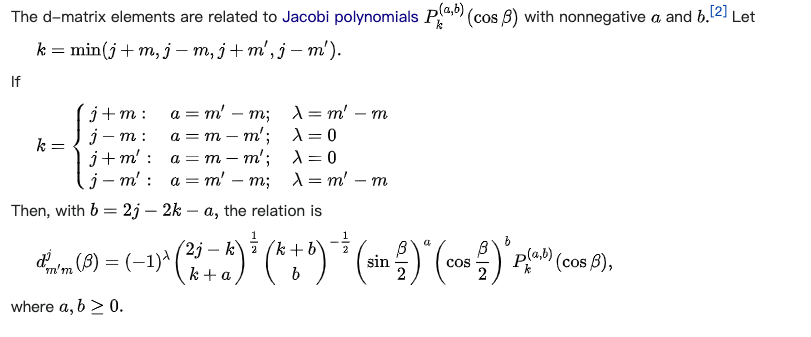

for j =[1]
    for m2 = -j:1:j
        for m1 = m2:1:j
            if m1<=0 && m2<0
            else
                SymPre =TBkit.SymbolicVarible('d',j,[m1,m2]);
                %SymExpr = Y_l__m.d_mm__j(j,m1,m2,sym('beta'));
                SymExpr = Y_l__m.d(j,m1,m2,sym('beta'));
                disp(SymPre == SymExpr);
            end
        end
    end
end

$$d_{1,\bar{1}}^{1}=\frac{1}{2}-\frac{\cos\left(\beta \right)}{2}$$

$$d_{0,0}^{1}=\cos\left(\beta \right)$$

$$d_{1,0}^{1}=-\frac{\sqrt{2}\,\sin\left(\beta \right)}{2}$$

$$d_{1,1}^{1}=\frac{\cos\left(\beta \right)}{2}+\frac{1}{2}$$

### Rotation of basis

#### Rotation of $Y_l^m$

- **wiki example**

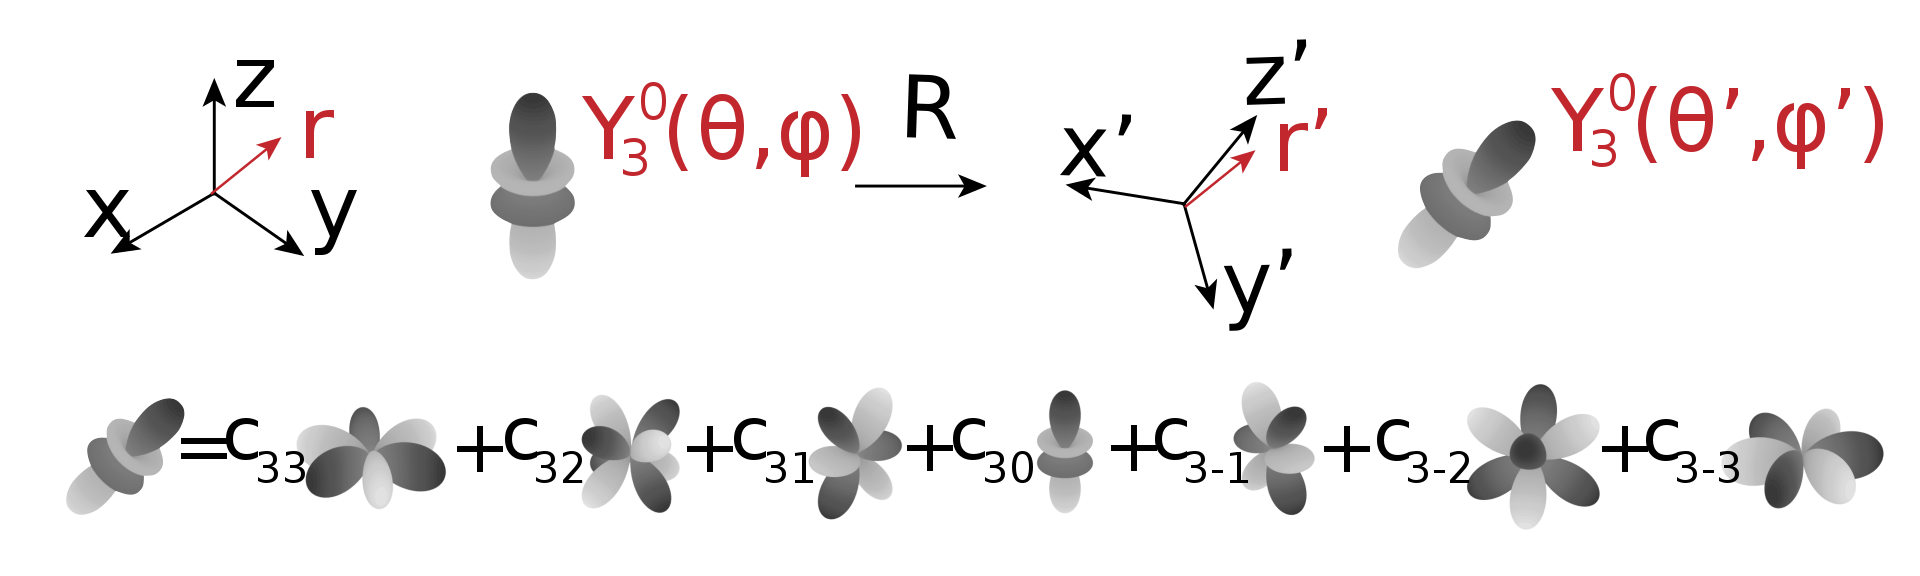

The rotation of a real spherical function with *m* = 0 and *ℓ* = 3. The coefficients are not equal to the Wigner D-matrices, since real functions are shown, but can be obtained by re-decomposing the complex functions

- **standard way**


$$Y_{\ell}^{m}\left(\mathbf{r}^{\prime}\right)=\sum_{m^{\prime}=-\ell}^{\ell}\left[D_{m m^{\prime}}^{(\ell)}(\mathcal{R})\right]^{*} Y_{\ell}^{m^{\prime}}(\mathbf{r})$$


where $\left[D_{m m^{\prime}}^{(\ell)}(\mathcal{R})\right]^{*} $ is the complex conjugate of an element of the [Wigner D-matrix](https://en.wikipedia.org/wiki/Wigner_D-matrix). In particular when $Y_l^m \left({\mathit{\mathbf{r}}}^{\prime } \right)$ is a $\phi_0$ rotation of the azimuth we get the identity,


$$Y_{\ell}^{m}\left(\mathbf{r}^{\prime}\right)=Y_{\ell}^{m}(\mathbf{r}) e^{i m \phi_{0}}$$



$$D_{m m^{\prime}}^{j}(\alpha, \beta, \gamma) \equiv\left\langle j m|\mathcal{R}(\alpha, \beta, \gamma)| j m^{\prime}\right\rangle=e^{-i  m \alpha} d_{m m^{\prime}}^{j}(\beta) e^{-i m^{\prime} \gamma}$$


py = Y_lm(1,-1);
RotatePy = py.rotate([0 0 1 sym(2*pi/3) 1]);
py.disp('vpa',false,'cart',true)

$$p_{y}$$

RotatePy.disp('vpa',false,'cart',true)

$$-\frac{p_{y}}{2}-\frac{\sqrt{3}\,p_{x}}{2}$$

#### More rotation

YlmBasisP = [Y_lm(1,1);Y_lm(1,-1);Y_lm(1,0);]

YlmBasisP = p_x
p_y
p_z
 

YlmBasisP.rotate([0 0 1 sym(2*pi/3) 1])

ans =   (3^(1/2)*p_y)/2 - p_x/2
- (3^(1/2)*p_x)/2 - p_y/2
                      p_z
 

syms x y z real;
PHI = [x;y;z];
C3z = Oper.rotation(1/3,[0,0,1]);
PHI_rot = C3z.R *PHI

$$PHI\_rot = \left(\begin{array}{c} \frac{\sqrt{3}\,y}{2}-\frac{x}{2}\\ -\frac{y}{2}-\frac{\sqrt{3}\,x}{2}\\ z \end{array}\right)$$

YlmBasis = [Y_lm(2,1);Y_lm(2,-1);Y_lm(3,2);Y_lm(3,-2);]

YlmBasis =     d_xz
    d_yz
f_zx2my2
   f_xyz
 

YlmBasis.rotate([0 0 1 sym(2*pi/3) 1])

ans =        (3^(1/2)*d_yz)/2 - d_xz/2
     - (3^(1/2)*d_xz)/2 - d_yz/2
- (3^(1/2)*f_xyz)/2 - f_zx2my2/2
  (3^(1/2)*f_zx2my2)/2 - f_xyz/2
 

phi1 = x*z;
phi2 = y*z;
phi3 = z*(x^2-y^2);
phi4 = 2*x*y*z;
PHI2 = [phi1;phi2;phi3;phi4]

$$PHI2 = \left(\begin{array}{c} x\,z\\ y\,z\\ z\,\left(-y^{2}+x^{2}\right)\\ 2\,x\,y\,z \end{array}\right)$$

expand(subs(PHI2,PHI,PHI_rot))

$$ans = \left(\begin{array}{c} \frac{\sqrt{3}\,y\,z}{2}-\frac{x\,z}{2}\\ -\frac{y\,z}{2}-\frac{\sqrt{3}\,x\,z}{2}\\ \frac{y^{2}\,z}{2}-\sqrt{3}\,x\,y\,z-\frac{x^{2}\,z}{2}\\ -\frac{\sqrt{3}\,y^{2}\,z}{2}-x\,y\,z+\frac{\sqrt{3}\,x^{2}\,z}{2} \end{array}\right)$$

#### % Rotation of $Y_{\textrm{lm}}$with Qnum class - with Matlab(Python) ... 

% py = Y_lm(1,-1);


### Coordinate Transformations and Trajectories in MATLAB

注意我们需要这些库

  [Navigation Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'NV', 'focused', 'axang2rotm');)

  [Robotics System Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'RO', 'focused', 'axang2rotm');)

  [UAV Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'UV', 'focused', 'axang2rotm');)

- [`axang2quat`](https://ww2.mathworks.cn/help/robotics/ref/axang2quat.html) Convert axis-angle rotation to quaternion

- [`axang2rotm`](https://ww2.mathworks.cn/help/robotics/ref/axang2rotm.html) Convert axis-angle rotation to rotation matrix

- [`axang2tform`](https://ww2.mathworks.cn/help/robotics/ref/axang2tform.html) Convert axis-angle rotation to homogeneous transformation

- [`eul2quat`](https://ww2.mathworks.cn/help/robotics/ref/eul2quat.html)Convert Euler angles to quaternion

- [`eul2rotm`](https://ww2.mathworks.cn/help/robotics/ref/eul2rotm.html)Convert Euler angles to rotation matrix

- [`eul2tform`](https://ww2.mathworks.cn/help/robotics/ref/eul2tform.html)Convert Euler angles to homogeneous transformation

- [`quat2axang`](https://ww2.mathworks.cn/help/robotics/ref/quat2axang.html)Convert quaternion to axis-angle rotation

- [`quat2eul`](https://ww2.mathworks.cn/help/robotics/ref/quat2eul.html)Convert quaternion to Euler angles

- [`quat2rotm`](https://ww2.mathworks.cn/help/robotics/ref/quat2rotm.html)Convert quaternion to rotation matrix

- [`quat2tform`](https://ww2.mathworks.cn/help/robotics/ref/quat2tform.html)Convert quaternion to homogeneous transformation

- [`quaternion`](https://ww2.mathworks.cn/help/robotics/ref/quaternion.html)Create a quaternion array

- [`rotm2axang`](https://ww2.mathworks.cn/help/robotics/ref/rotm2axang.html)Convert rotation matrix to axis-angle rotation

- [`rotm2eul`](https://ww2.mathworks.cn/help/robotics/ref/rotm2eul.html)Convert rotation matrix to Euler angles

- [`rotm2quat`](https://ww2.mathworks.cn/help/robotics/ref/rotm2quat.html)Convert rotation matrix to quaternion

- [`rotm2tform`](https://ww2.mathworks.cn/help/robotics/ref/rotm2tform.html)Convert rotation matrix to homogeneous transformation

- [`tform2axang`](https://ww2.mathworks.cn/help/robotics/ref/tform2axang.html)Convert homogeneous transformation to axis-angle rotation

- [`tform2eul`](https://ww2.mathworks.cn/help/robotics/ref/tform2eul.html)Extract Euler angles from homogeneous transformation

- [`tform2quat`](https://ww2.mathworks.cn/help/robotics/ref/tform2quat.html)Extract quaternion from homogeneous transformation

- [`tform2rotm`](https://ww2.mathworks.cn/help/robotics/ref/tform2rotm.html)Extract rotation matrix from homogeneous transformation

- [`tform2trvec`](https://ww2.mathworks.cn/help/robotics/ref/tform2trvec.html)Extract translation vector from homogeneous transformation

- [`angdiff`](https://ww2.mathworks.cn/help/robotics/ref/angdiff.html)Difference between two angles

- [`cart2hom`](https://ww2.mathworks.cn/help/robotics/ref/cart2hom.html)Convert Cartesian coordinates to homogeneous coordinates

- [`hom2cart`](https://ww2.mathworks.cn/help/robotics/ref/hom2cart.html)Convert homogeneous coordinates to Cartesian coordinates

- [`trvec2tform`](https://ww2.mathworks.cn/help/robotics/ref/trvec2tform.html)Convert translation vector to homogeneous transformation

C3z = Oper.rotation(1/3,[0 0 -1])

C3z =   Oper with properties:

               e: 0
               R: [3×3 double]
               t: [0 0 0]
       conjugate: 0
    antisymmetry: 0
              Rf: []
              tf: [0 0 0]
               U: NaN

U·H(k)·U^-1 = H(R·k)
R = R((2*pi)/3,[0 0 1])


C3z.R

ans =    -0.5000   -0.8660         0
    0.8660   -0.5000         0
         0         0    1.0000


C3z_axang = rotm2axang(C3z.R)

C3z_axang =          0         0    1.0000    2.0944


C3z_rotm = axang2rotm([0 0 -1 2*pi/3])

C3z_rotm =    -0.5000    0.8660         0
   -0.8660   -0.5000         0
         0         0    1.0000


C3z_eul = rotm2eul(C3z_rotm,'ZYZ')

C3z_eul =          0         0   -2.0944


Oper.Rotation2eul(C3z_rotm)

ans =          0         0   -2.0944


#### symbolical check

syms theta real;
%assume(theta>0 & theta<pi/2);
assume(theta>pi/2 & theta<pi);
theta

$$theta = \theta$$

sign(sin(theta))

$$ans = 1$$

simplify(atan(sin(theta)/cos(theta)),'IgnoreAnalyticConstraints',true)

$$ans = \theta$$

simplify(atan2(sin(theta),cos(theta)),'IgnoreAnalyticConstraints',true)

$$ans = \pi +\theta$$

C3z = Oper.rotation(theta,[0 0 -1])

C3z =   Oper with properties:

               e: 0
               R: [3×3 sym]
               t: [0 0 0]
       conjugate: 0
    antisymmetry: 0
              Rf: []
              tf: [0 0 0]
               U: NaN

U·H(k)·U^-1 = H(R·k)
R = R(theta,["0" "0" "1"])


C3z.R

$$ans = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

[C3z_n,theta] = (Oper.Rotation2nTheta(C3z.R))

$$C3z\_n = \left(\begin{array}{ccc} 0 & 0 & 1 \end{array}\right)$$

$$theta = \theta$$

eul = Oper.Rotation2eul(C3z.R)

$$eul = \left(\begin{array}{ccc} 0 & 0 & \pi +\theta \end{array}\right)$$

simplify(eul ,'IgnoreAnalyticConstraints',true)

$$ans = \left(\begin{array}{ccc} 0 & 0 & \pi +\theta \end{array}\right)$$

% C3z_axang = rotm2axang(C3z.R)
% C3z_rotm = axang2rotm(C3z_axang)
% C3z_eul = rotm2eul(C3z_rotm,'ZYZ')
% Oper.Rotation2eul(C3z_rotm)


## Spherical Harmonic Tools-python

### Use python in matlab

pyversion

       version: '3.9'
    executable: '/Applications/Xcode.app/Contents/Developer/usr/bin/python3'
       library: '/Applications/Xcode.app/Contents/Developer/Library/Frameworks/Python3.framework/Versions/3.9/lib/libpython3.9.dylib'
          home: '/Applications/Xcode.app/Contents/Developer/Library/Frameworks/Python3.framework/Versions/3.9'
      isloaded: 0



%pe = pyenv('Version','/Users/parkman/Documents/TOOLs/miniconda2/envs/my_pymatgen/bin/python')

#### `import`` module`

%pysh = py.importlib.import_module('pyshtools'); 

#### **使用 Python** `textwrap` **模块**

MATLAB 具有 [Python 标准库](https://docs.python.org/2/library/)的大量等效功能，但并非全部。例如，`textwrap` 是一个模块，它可使用回车和其他便捷方式格式化文本块。MATLAB 同样提供了一个 `textwrap` 函数，但该函数只允许文本为适应 UI 控件而换行。

创建一个文本段落来进行测试。

%T = 'We at MathWorks believe in the importance of engineers and scientists. They increase human knowledge and profoundly improve our standard of living.';

**将 Python 字符串转换为 MATLAB 字符串**

通过在 `textwrap.wrap` 函数名称之前输入字符 `py.` 来调用该函数。请勿输入 `import textwrap`。

%wrapped = py.textwrap.wrap(T);
% whos wrapped
% wrapped = cell(wrapped);
% whos wrapped
% wrapped{1}
% wrapped = cellfun(@char, wrapped, 'UniformOutput', false);
% wrapped{1}

**自定义段落**

使用关键字参数自定义段落的输出。

前面的代码使用 `wrap` 便利函数，但模块使用 `py.textwap.TextWrapper` 功能提供更多选项。若要使用这些选项，请使用 [https://docs.python.org/2/library/textwrap.html#textwrap.TextWrapper](https://docs.python.org/2/library/textwrap.html#textwrap.TextWrapper) 所述的关键字参数调用 `py.textwap.TextWrapper`。

结合使用 MATLAB `pyargs` 函数与逗号分隔的名称/值对组列表创建关键字参数。`width` 将文本格式化为 30 个字符宽。`initial_indent` 和 `subsequent_indent` 关键字使每一行以 MATLAB 所用的注释字符 `%` 开头。

% tw = py.textwrap.TextWrapper(pyargs(...
%     'initial_indent', '% ', ...
%     'subsequent_indent', '% ', ...
%     'width', int32(30)));
% wrapped = tw.wrap(T);
% wrapped = cellfun(@char, cell(wrapped), 'UniformOutput', false);
% fprintf('%s\n', wrapped{:})